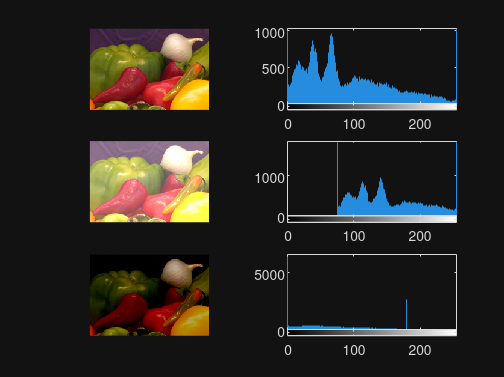


%% perform various arithmetic operation (image, addition,subtraction)
%% Image complement
%% Logical operation (NOT,OR and XOR)
clc;
clear all;
close all;
% step-1: Image arithematic (add,sub)
a=imread('onion.png');
s=imadd (a,75);
subplot(3,2,1); imshow(a);
subplot(3,2,2); imhist(a);
subplot(3,2,3); imshow(s);
subplot(3,2,4); imhist(s);
d=imsubtract(a,75);
subplot(3,2,5); imshow(d);
subplot(3,2,6); imhist(d);

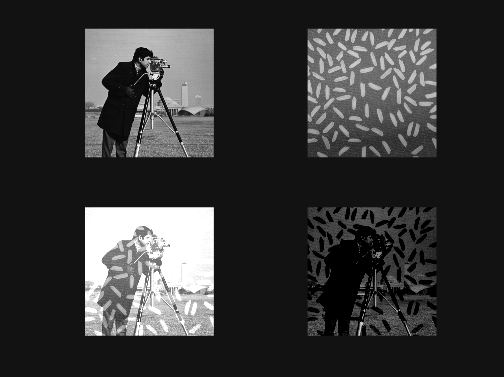

img1=imread('cameraman.tif');
img2=imread('rice.png');
img2_resize=imresize(img2,size(img1));
img_add=imadd(img1,img2_resize);
figure;
subplot(2,2,1); imshow(img1);
subplot(2,2,2); imshow(img2_resize);
subplot(2,2,3); imshow(img_add);
img_sub=imsubtract(img1,img2_resize);
subplot(2,2,4);imshow(img_sub);

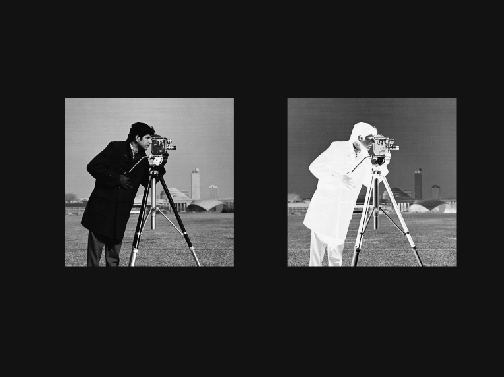

%step-2 Image Complement
img_comp=imcomplement(img1);
figure;
subplot(1,2,1);imshow(img1);
subplot(1,2,2);imshow(img_comp);

%step-3 Logical Operation
a= imread ("black2.png");

Error using imread>get_full_filename (line 635)
Unable to find file "black2.png".

Error in imread (line 395)
        fullname = get_full_filename(filename);
        ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

b= imread ("white.png");
%Image color to grey
 a= rgb2gray(a);
 b= rgb2gray(b);
%Image in binary
 a1=im2bw(a,0.5);
 b1=im2bw(b,0.5);
 %image resize
 [r1,c1,chan]=size(a1);
 b1=imresize(b1,[r1,c1])
 %logical operation
 c1=not(a1);
 d1=and(a1,b1);
 e1=or(a1,b1);
 f1=xor(a1,b1);
 figure;
 subplot (2,3,1);
 imshow(a1);
 title("BinaryImage 1");
 subplot (2,3,2);
 imshow(b1);
 title("BinaryImage 2");
 subplot (2,3,3);
 imshow(c1);
 title("NOT operation");
 subplot (2,3,4);
 imshow(d1);
 title("AND operation");
  subplot (2,3,5);
  imshow(e1);
  title("OR operation");
   subplot (2,3,6);
 imshow(f1);
 title("XOR operation");


 
